# AP_TECS.cpp

## Introdução

O objetivo deste script é calcular os ganhos da arquitetura de controle já proposta pela Ardupilot.

clear
close all
cd('../')
main
cd('GNC')

load('../MVO/Results/SteadyState.mat')
model = 'TelemasterTrimLin';
load_system(model)

## Taxa de Atualização do Controlador

Na Ardupilot, o controlador TECS roda a cada 50Hz, vou iniciar o projeto considerando esta taxa. Para verificar se essa taxa atende a nossa dinâmica, é necessário realizar a análise da banda passante das funções transferência de Arfagem $\frac{\theta \;}{\delta_e }$ e Velocidade  $\frac{V}{\delta_T }$. O gráfico demonstra que a dinâmica mais rápida do modo longitudinal da aeronave é de aproximadamente $1\ldotp 2\textrm{Hz}$, sendo desta forma o autopiloto capaz de responder a dinâmica da aeronave.

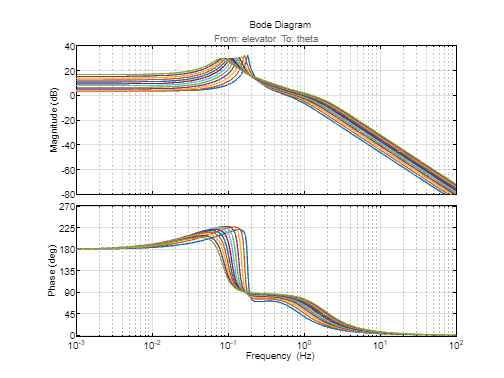

figure(1)
title('Altitude')
opt = bodeoptions;
opt.FreqUnits = 'Hz';
opt.Grid = 'on';
for cont = 1:length(SteadyState)
    if ~isempty(SteadyState(cont).G_lon)
        bode(SteadyState(cont).G_lon(4,2),opt)
        hold on
    end
end
hold off

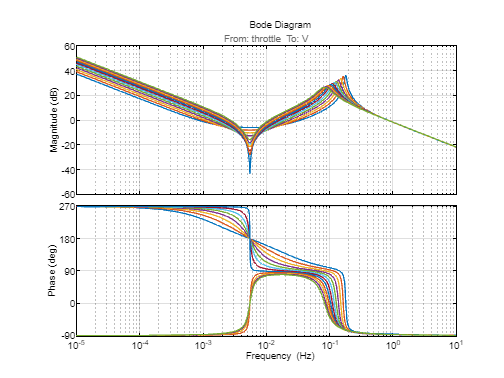

figure(2)
title('Velocidade')
for cont = 1:length(SteadyState)
    if ~isempty(SteadyState(cont).G_lon)
        bode(SteadyState(cont).G_lon(1,1),opt)
        hold on
    end
end
hold off

## Parâmetros da Arquitetura do Controlador

Nesta seção serão obtidos os parâmetros da Arquitetura proposta pela Ardupilot que se aplicam ao projeto do controlador.

TECS.Vcruise            = 13;
TECS.Vmax               = 20;
TECS.Vmin               = 9;
TECS.ControlRate        = 50;
TECS.spdCompFiltOmega   = 2;
TECS.hgt_dem_tconst     = 3;
TECS.timeConst          = 3;
TECS.rollComp           = 10;
TECS.integGain          = 0.3;
TECS.spdWeight          = 1;
TECS.nomThr             = 0;
TECS.ClimbMax           = 0;
TECS.SinkMin            = 0;
TECS.PitchMax           = 0;
TECS.SinkMax            = 0;
TECS.PitchMin           = 0;
TECS.ptchDamp           = 1; 
TECS.thrDamp            = 0.5; 
TECS.hgt_dem_tconst     = 3; 
TECS.integGain          = 0.3;
TECS.Timeconst          = 5;

### `TRIM_THROTTLE`

idx = find([SteadyState.V] == TECS.Vcruise);
TECS.nomThr = SteadyState(idx).thr;

### `CLMB_MAX`

`Descrição: Maximum demanded climb rate. Do not set higher than the climb speed at THR_MAX at AIRSPEED_CRUISE when the battery is at low voltage. Reduce value if airspeed cannot be maintained on ascent. Increase value if throttle does not increase significantly to ascend.`

`Método de obtenção: Trimar a aeronave com Velocidade de Cruzeiro (V = 13 m/s) e Throttle = 100%. Deixar a restrição de velocidade vertical livre.`

throttle = 1;
[ClimbMax,~,~] = trim_Climb(TECS.Vcruise,throttle,model);
TECS.ClimbMax = -ClimbMax;

### `SINK_MIN`

`Descrição: Minimum sink rate when at THR_MIN and AIRSPEED_CRUISE.`

`Método de obtenção: Trimar a aeronave com Velocidade de Cruzeiro (V = 13 m/s) e Throttle = 0%. Deixar a restrição de velocidade vertical livre.`

throttle = 0;
[TECS.SinkMin,~,~]  = trim_Climb(TECS.Vcruise,throttle,model);

### `VERT_ACC`

`Descrição: Maximum vertical acceleration used to correct speed or height errors.`

`Método de obtenção: Realizar uma simulação partindo da trimagem em velocidade de cruzeiro, após 1 segundo aplicar profundor batente negativo, motor no máximo e obter a aceleração máxima dessa manobra.`

`Obs. Deve-se checar se o valor obtido não é maior que o limite estrutural da aeronave.`

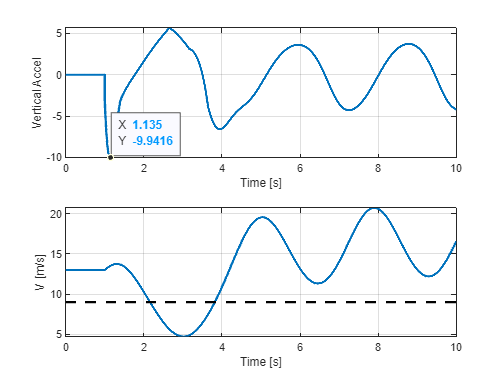

u(:,2) = SteadyState(idx).op.Inputs(2, 1).u;
u(:,3) = SteadyState(idx).op.Inputs(3, 1).u;
for cont = 1:length(t)
    if t(cont) > 1
        u(cont,2) = 1;
        u(cont,3) = -20;
    end
end
set_param(model,'LoadInitialState','on','InitialState','getstatestruct(SteadyState(idx).op)','LoadExternalInput','on')
res_vertAccLim = sim(model);
figure()
subplot(2,1,1)
plot(res_vertAccLim.tout,-res_vertAccLim.yout.signals(3).values,LineWidth=2)
hold on
ax = gca;
chart = ax.Children(1);
datatip(chart,1.135,-9.942);
grid on
xlabel('Time [s]')
ylabel('Vertical Accel')
subplot(2,1,2)
plot(res_vertAccLim.tout,res_vertAccLim.yout.signals(27).values,LineWidth=2)
hold on
plot([res_vertAccLim.tout(1) res_vertAccLim.tout(end)],[9 9],'k--',LineWidth=2)
grid on
xlabel('Time [s]')
ylabel('V [m/s]')

### `PITCH_MAX`

`Descrição: For proper TECS tuning, set to the angle that the aircraft can climb at AIRSPEED_CRUISE and THR_MAX.`

`Método de Obtenção: Trimar a aeronave com Velocidade de Cruzeiro (V = 13 m/s) e Throttle = 100%. Deixar a restrição de velocidade vertical livre.`

throttle = 1;
[~,~,TECS.PitchMax]  = trim_Climb(TECS.Vcruise,throttle,model);

### `SINK_MAX`

`Descrição: Maximum demanded descent rate. Do not set higher than the vertical speed the aircraft can maintain at THR_MIN, TECS_PITCH_MIN, and AIRSPEED_MAX.`

`Método de Obtenção: Trimar a aeronave para descobrir o ângulo de arfagem necessário para manter a velocidade máxima de 20 m/s com o throttle em 20% e também obter a máxima razão de descida.`

throttle = 0.0;
set_param(model,'LoadInitialState','off','LoadExternalInput','off')
[TECS.SinkMax,~,~]  = trim_Climb(TECS.Vmax,throttle,model);

### `PITCH_MAX`

`Descrição: For proper TECS tuning, set to the angle that the aircraft can descend at without overspeeding.`

`Método de Obtenção: Trimar a aeronave com Velocidade Máxima (V = 20 m/s) e Throttle = 0%. Deixar a restrição de velocidade vertical livre.`

throttle = 0;
[~,~,TECS.PitchMin]  = trim_Climb(TECS.Vmax,throttle,model);

### `PTCH_DAMP`

`Descrição: Damping gain for pitch control from TECS control.  Increasing may correct for oscillations in speed and height, but too much may cause additional oscillation and degraded control.`

TECS.ptchDamp = 0.3; % Default

### `THR_DAMP`

`Descrição: Damping gain for throttle demand loop. Increase to add throttle activity to dampen oscillations in speed and height.`

TECS.thrDamp = 0.5; % Default

### `HDEM_TCONST`

`Descrição: This sets the time constant of the low pass filter that is applied to the height demand input when bit 1 of TECS_OPTIONS is not selected.`

TECS.hgt_dem_tconst = 3; % Default

### `INTEG_GAIN`

`Descrição: Integrator gain to trim out long-term speed and height errors.`

TECS.integGain = 0.3;

### `TIME_CONST`

`Descrição: Time constant of the TECS control algorithm. Small values make faster altitude corrections but can cause overshoot and aggressive behavior.`

TECS.Timeconst = 5;

## `Projeto`


dt = 1/4000;
t = 0:dt:40;
t = t.';
u = zeros(length(t),4);
u(:,2)   = SteadyState(idx).op.Inputs(2, 1).u;
u(:,3)   = SteadyState(idx).op.Inputs(3, 1).u;
TO.u     = SteadyState(idx).op.States(7).x;
TO.v     = SteadyState(idx).op.States(8).x;
TO.w     = SteadyState(idx).op.States(9).x;
TO.p     = SteadyState(idx).op.States(4).x;
TO.q     = SteadyState(idx).op.States(5).x;
TO.r     = SteadyState(idx).op.States(6).x;
TO.phi   = SteadyState(idx).op.States(1).x;
TO.theta = SteadyState(idx).op.States(2).x;
TO.psi   = SteadyState(idx).op.States(3).x;
TO.x     = SteadyState(idx).op.States(10).x;
TO.y     = SteadyState(idx).op.States(11).x;
TO.z     = SteadyState(idx).op.States(12).x;
TO.alt0  = 0; 